# Graphene

## Graphene

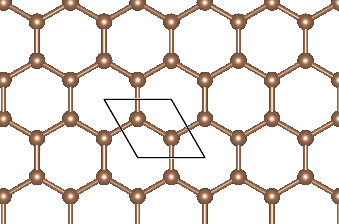

### Pre

syms t a k_x k_y real;
bond = sqrt(3)/3 *a;
delta(1,:) = a*[1/2,-sqrt(3)/6];
delta(2,:) = a*[  0,    bond/a];
delta(3,:) = a*[-1/2,-sqrt(3)/6];
sigma_x = pauli_matric(1);
sigma_y = pauli_matric(2);
sigma_z = pauli_matric(3);
k = [k_x k_y].';

### Model

Graphene = Htrig(2);
Graphene = Graphene +...
    Trig(-t*cos(delta(1,:)*k),sigma_x)+...
    Trig( t*sin(delta(1,:)*k),sigma_y)+...
    Trig(-t*cos(delta(2,:)*k),sigma_x)+...
    Trig( t*sin(delta(2,:)*k),sigma_y)+...
    Trig(-t*cos(delta(3,:)*k),sigma_x)+...
    Trig( t*sin(delta(3,:)*k),sigma_y);

Setting 2/2Htrig ...


Setting 2/2Htrig ...


Setting 1/1Htrig ...


Setting 1/1Htrig ...


Setting 2/2Htrig ...


Setting 2/2Htrig ...


Graphene_sym = Graphene.Htrig_sym

$$Graphene\_sym = \begin{array}{l} \left(\begin{array}{cc} 0 & -t\,\cos\left(\frac{\sqrt{3}\,a\,k_{y}}{3}\right)-t\,\sin\left(\frac{\sqrt{3}\,a\,k_{y}}{3}\right)\,\mathrm{i}-\sigma_{2}+\sigma_{1}\\ -t\,\cos\left(\frac{\sqrt{3}\,a\,k_{y}}{3}\right)+t\,\sin\left(\frac{\sqrt{3}\,a\,k_{y}}{3}\right)\,\mathrm{i}-\sigma_{2}-\sigma_{1} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,t\,\cos\left(\frac{a\,k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,a\,k_{y}}{6}\right)\,\mathrm{i}\\ \sigma_{2}=2\,t\,\cos\left(\frac{a\,k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,a\,k_{y}}{6}\right) \end{array}$$

Graphene_sym = simplify(rewrite(Graphene_sym,'exp'))

$$Graphene\_sym = \begin{array}{l} \left(\begin{array}{cc} 0 & -t\,{\mathrm{e}}^{\frac{\sqrt{3}\,a\,k_{y}\,\mathrm{i}}{3}}-t\,{\mathrm{e}}^{-\frac{a\,k_{x}\,\mathrm{i}}{2}}\,\sigma_{1}-t\,{\mathrm{e}}^{\frac{a\,k_{x}\,\mathrm{i}}{2}}\,\sigma_{1}\\ -t\,{\mathrm{e}}^{-\frac{\sqrt{3}\,a\,k_{y}\,\mathrm{i}}{3}}-t\,{\mathrm{e}}^{-\frac{a\,k_{x}\,\mathrm{i}}{2}}\,\sigma_{2}-t\,{\mathrm{e}}^{\frac{a\,k_{x}\,\mathrm{i}}{2}}\,\sigma_{2} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{\sqrt{3}\,a\,k_{y}\,\mathrm{i}}{6}}\\ \sigma_{2}={\mathrm{e}}^{\frac{\sqrt{3}\,a\,k_{y}\,\mathrm{i}}{6}} \end{array}$$

### Band

a = 1;t =1;
Graphene_n  = Graphene.Subsall();
Graphene_n = Graphene_n<'POSCAR';
Graphene_n = Graphene_n <'KPOINTS';
EIGENCAR = Graphene_n.EIGENCAR_gen();
[klist_l,kpoints_l,kpoints_name] = Graphene_n.kpath_information();
bandplot(EIGENCAR,[-3,3],klist_l,kpoints_l,kpoints_name,'title','Graphene','Color','r');

## Kane-Mele

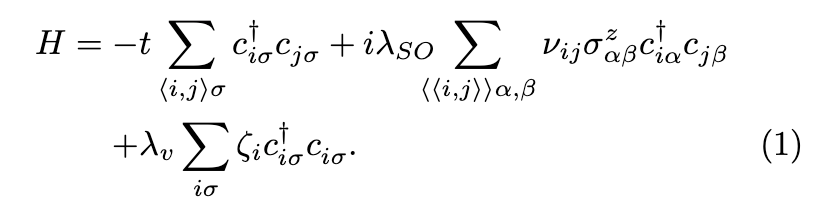

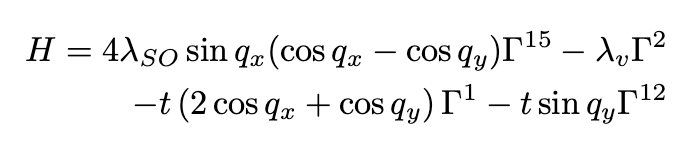

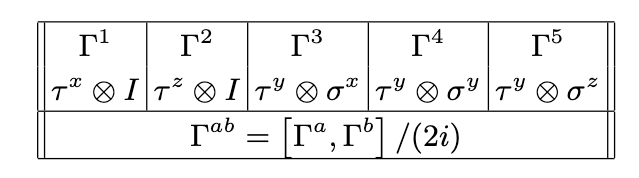

### Model

syms t a lambda_SO lambda_v lambda_R Mz k_x k_y real;
syms q_x q_y;
sigma_z = pauli_matric(3);
sigma_0 = pauli_matric(0);
q_x = k_x/2;
q_y = sqrt(3)/2 *k_y;
KaneMele = Htrig(4);
KaneMele = KaneMele+...
    Trig(4*lambda_SO*sin(q_x)*(cos(q_x)-cos(q_y)),gamma_matric(1,5))+...
    Trig(-lambda_v                               ,gamma_matric(3  ))+...
    Trig(-t*(2*cos(q_x)+cos(q_y))                ,gamma_matric(1  ))+...
    Trig(-t*(sin(q_y))                           ,gamma_matric(1,3))+...
    Trig(4*lambda_SO*sin(q_x)*(cos(q_x)-cos(q_y)),gamma_matric(1,5))+...
    Trig(lambda_R*(1-cos(q_x)*cos(q_y))          ,gamma_matric(4  ))+...
    Trig(-sqrt(3)*lambda_R*sin(q_x)*sin(q_y)     ,gamma_matric(2  ))+...
    Trig(-lambda_R*cos(q_x)*sin(q_y)             ,gamma_matric(3,4))+...
    Trig(sqrt(3)*lambda_R*sin(q_x)*cos(q_y)      ,gamma_matric(3,2))+...
    Trig(Mz                                      ,sigma_z*sigma_0);

Setting 2/2Htrig ...


Setting 1/1Htrig ...


Setting 2/2Htrig ...


Setting 1/1Htrig ...


Setting 2/2Htrig ...


Setting 2/2Htrig ...


Setting 1/1Htrig ...


Setting 1/1Htrig ...


Setting 1/1Htrig ...


Setting 1/1Htrig ...


### Analitical

H_KaneMele = simplify(KaneMele.Htrig_sym)

$$H\_KaneMele = \begin{array}{l} \left(\begin{array}{cccc} \mathrm{Mz}-\lambda_{v}+\sigma_{1}-\sigma_{3} & \sigma_{8} & 0 & \lambda_{R}\,\left(\sigma_{5}+\sigma_{6}+\sigma_{2}+\sigma_{4}-\mathrm{i}\right)\\ \sigma_{7} & \mathrm{Mz}+\lambda_{v}-\sigma_{1}+\sigma_{3} & \lambda_{R}\,\left(\sigma_{6}-\sigma_{5}+\sigma_{2}-\sigma_{4}+\mathrm{i}\right) & 0\\ 0 & -\lambda_{R}\,\left(\sigma_{4}-\sigma_{6}+\sigma_{2}-\sigma_{5}+\mathrm{i}\right) & \sigma_{3}-\lambda_{v}-\sigma_{1}-\mathrm{Mz} & \sigma_{8}\\ \lambda_{R}\,\left(\sigma_{6}-\sigma_{5}-\sigma_{2}+\sigma_{4}+\mathrm{i}\right) & 0 & \sigma_{7} & \lambda_{v}-\mathrm{Mz}+\sigma_{1}-\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=4\,\lambda_{\mathrm{SO}}\,\sin\left(k_{x}\right)\\ \sigma_{2}=\sqrt{3}\,\sin\left(\frac{k_{x}}{2}\right)\,\sigma_{9}\,\mathrm{i}\\ \sigma_{3}=8\,\lambda_{\mathrm{SO}}\,\sin\left(\frac{k_{x}}{2}\right)\,\sigma_{9}\\ \sigma_{4}=\sqrt{3}\,\sin\left(\frac{k_{x}}{2}\right)\,\sigma_{10}\\ \sigma_{5}=\cos\left(\frac{k_{x}}{2}\right)\,\sigma_{9}\,\mathrm{i}\\ \sigma_{6}=\cos\left(\frac{k_{x}}{2}\right)\,\sigma_{10}\\ \sigma_{7}=-t\,\left(2\,\cos\left(\frac{k_{x}}{2}\right)+\sigma_{9}-\sigma_{10}\,\mathrm{i}\right)\\ \sigma_{8}=-t\,\left(2\,\cos\left(\frac{k_{x}}{2}\right)+\sigma_{9}+\sigma_{10}\,\mathrm{i}\right)\\ \sigma_{9}=\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\\ \sigma_{10}=\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right) \end{array}$$

%fprintf('When lambda_v = 0\n');
%simplify(eig(subs(H_KaneMele,[lambda_v], 0)))
fprintf('When k = K \n');

When k = K 


K_solved = simplify(eig(subs(H_KaneMele,[k_x k_y], 2*pi*sym([1/3,sqrt(3)/3]))))

K_solved = subs(K_solved,[lambda_v],0)

K_solved = subs(K_solved,[lambda_SO],0)

$$K\_solved = \begin{array}{l} \left(\begin{array}{c} -\sigma_{2}\\ \sigma_{1}\\ -\sigma_{1}\\ \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,\left(\sqrt{36\,{\lambda_{R}}^{2}\,{\left(-729\,{\lambda_{R}}^{6}\right)}^{1/3}\,\sqrt{\sigma_{3}}-81\,{\lambda_{R}}^{4}\,\sqrt{\sigma_{3}}-{\left(-729\,{\lambda_{R}}^{6}\right)}^{2/3}\,\sqrt{\sigma_{3}}}-{\sigma_{3}}^{3/4}\right)}{6\,{\left(-729\,{\lambda_{R}}^{6}\right)}^{1/6}\,{\sigma_{3}}^{1/4}}\\ \sigma_{2}=\frac{\sqrt{3}\,\left(\sqrt{36\,{\lambda_{R}}^{2}\,{\left(-729\,{\lambda_{R}}^{6}\right)}^{1/3}\,\sqrt{\sigma_{3}}-81\,{\lambda_{R}}^{4}\,\sqrt{\sigma_{3}}-{\left(-729\,{\lambda_{R}}^{6}\right)}^{2/3}\,\sqrt{\sigma_{3}}}+{\sigma_{3}}^{3/4}\right)}{6\,{\left(-729\,{\lambda_{R}}^{6}\right)}^{1/6}\,{\sigma_{3}}^{1/4}}\\ \sigma_{3}={\left(-729\,{\lambda_{R}}^{6}\right)}^{2/3}+18\,{\lambda_{R}}^{2}\,{\left(-729\,{\lambda_{R}}^{6}\right)}^{1/3}+81\,{\lambda_{R}}^{4} \end{array}$$

### Band

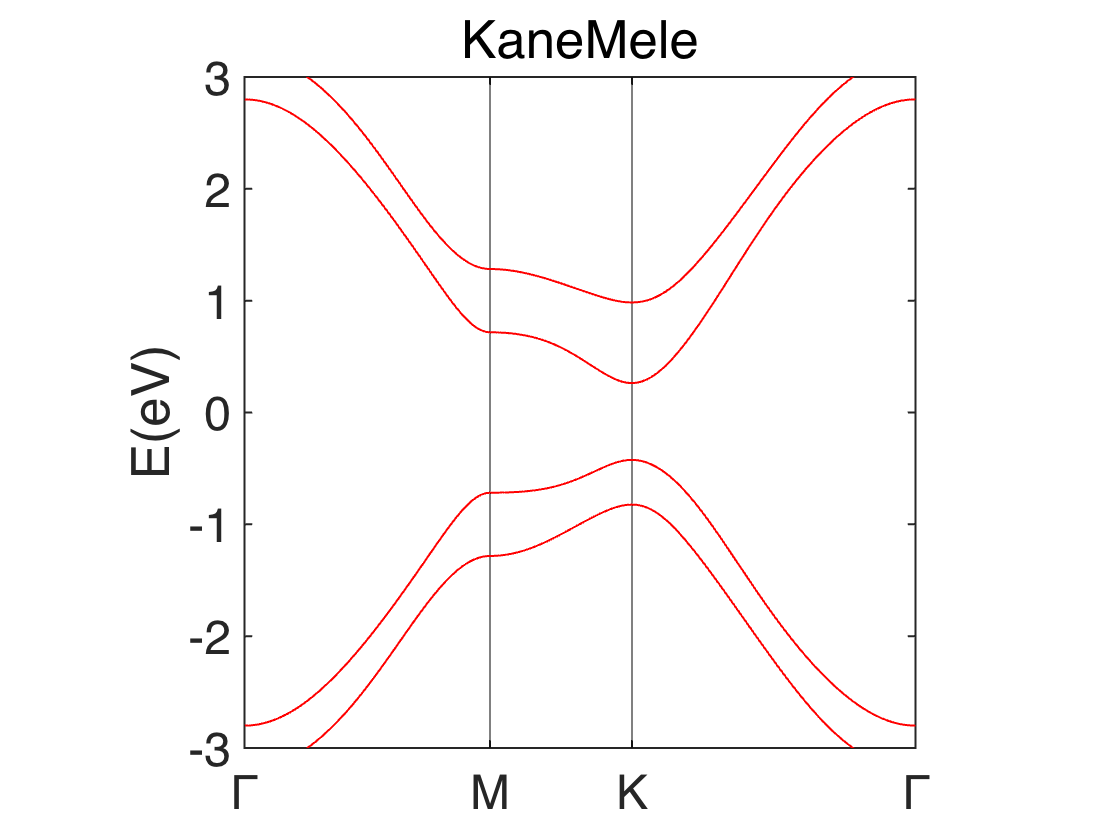

a = 1;t =1;lambda_SO =0.06;lambda_v=0.00;lambda_R = 0.1;Mz = 0.0;
KaneMele_n  = KaneMele.Subsall();
KaneMele_n = KaneMele_n<'POSCAR';
KaneMele_n = KaneMele_n <'KPOINTS';
EIGENCAR = KaneMele_n.EIGENCAR_gen();
[klist_l,kpoints_l,kpoints_name] = KaneMele_n.kpath_information();
bandplot(EIGENCAR,[-3,3],klist_l,kpoints_l,kpoints_name,'title','KaneMele','Color','r');

## Descitize in C3

### KaneMele-zigzag

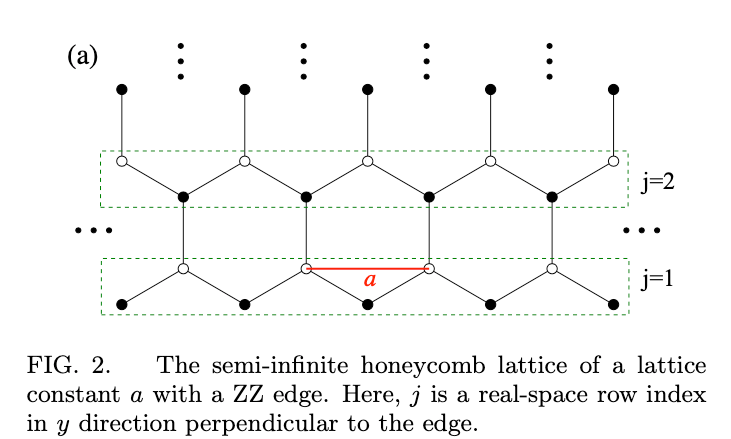

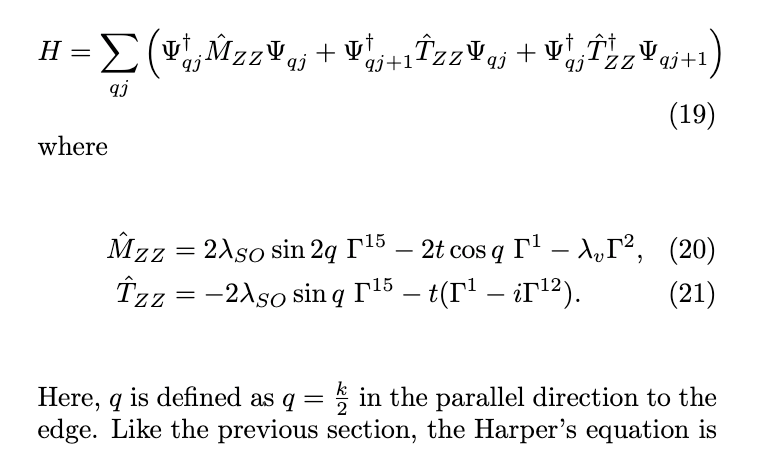

KaneMele.Rm = sym([1,0,0;-1/2,sqrt(3)/2,0;0 0 2/sqrt(3)])

KaneMele =   Htrig - 属性:

          Kinds: 9
          HcoeL: [4×4×9 sym]
          HnumL: [4×4×9 double]
     HsymL_trig: [1    cos(k_x/2)*sin(k_x/2)    sin(k_x/2)*cos((3^(1/2)*k_y)/2)    cos(k_x/2)    cos((3^(1/2)*k_y)/2)    sin((3^(1/2)*k_y)/2)    cos(k_x/2)*cos((3^(1/2)*k_y)/2)    sin(k_x/2)*sin((3^(1/2)*k_y)/2)    cos(k_x/2)*sin((3^(1/2)*k_y)/2)]
      Htrig_sym: [4×4 sym]
      Basis_num: 4
             Rm: [3×3 sym]
             Gk: [3×3 sym]
    symvar_list: [Mz    lambda_R    lambda_SO    lambda_v    t]

\left(\begin{array}{cccc} \mathrm{Mz}-\lambda _{v}+8\,\lambda _{\mathrm{SO}}\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{k_{x}}{2}\right)-8\,\lambda _{\mathrm{SO}}\,\sin\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right) & -2\,t\,\cos\left(\frac{k_{x}}{2}\right)-t\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)-t\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,1{}\mathrm{i} & 0 & \lambda _{R}\,\

KaneMele.orbL = [     0.333333333         0.666666667         0.50000000 ;...
    0.666666667         0.333333333         0.50000000;...
    0.333333333         0.666666667         0.50000000 ;...
    0.666666667         0.333333333         0.50000000...
    ];
KaneMele.Htrig_sym

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \mathrm{Mz}-\lambda_{v}+\sigma_{6}-\sigma_{3} & \sigma_{7} & 0 & \sigma_{5}+\sigma_{4}-\lambda_{R}\,\mathrm{i}+\sigma_{2}+\sigma_{1}\\ \sigma_{8} & \mathrm{Mz}+\lambda_{v}-\sigma_{6}+\sigma_{3} & \lambda_{R}\,\mathrm{i}-\sigma_{4}+\sigma_{5}-\sigma_{2}+\sigma_{1} & 0\\ 0 & \sigma_{5}+\sigma_{4}-\lambda_{R}\,\mathrm{i}-\sigma_{2}-\sigma_{1} & \sigma_{3}-\lambda_{v}-\sigma_{6}-\mathrm{Mz} & \sigma_{7}\\ \lambda_{R}\,\mathrm{i}-\sigma_{4}+\sigma_{5}+\sigma_{2}-\sigma_{1} & 0 & \sigma_{8} & \lambda_{v}-\mathrm{Mz}+\sigma_{6}-\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{3}\,\lambda_{R}\,\sin\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,\mathrm{i}\\ \sigma_{2}=\sqrt{3}\,\lambda_{R}\,\sin\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\\ \sigma_{3}=8\,\lambda_{\mathrm{SO}}\,\sin\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\\ \sigma_{4}=\lambda_{R}\,\cos\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,\mathrm{i}\\ \sigma_{5}=\lambda_{R}\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\\ \sigma_{6}=8\,\lambda_{\mathrm{SO}}\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{k_{x}}{2}\right)\\ \sigma_{7}=-2\,t\,\cos\left(\frac{k_{x}}{2}\right)-t\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)-t\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,\mathrm{i}\\ \sigma_{8}=-2\,t\,\cos\left(\frac{k_{x}}{2}\right)-t\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)+t\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,\mathrm{i} \end{array}$$

KaneMele.rotation().Htrig_sym

Setting 19/19Htrig ...


KaneMele_dy = KaneMele.descritize([0,30,0],'Rotation','auto');

Setting 19/19Htrig ...
Setting 13/13Htrig ...


KaneMele_dy.Htrig_sym

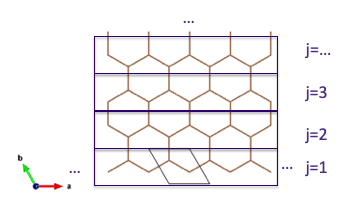

a = 1;t =1;lambda_SO =0.06;lambda_v=0.0,Mz = 0.2;

lambda_v = 0

KaneMele_dy = KaneMele_dy<'KPOINTS_slab';

[klist_l,kpoints_l,kpoints_name] = KaneMele_dy.kpath_information();
% KaneMele_dy.HcoeL = subs(KaneMele_dy.HcoeL);
% RCI_d = RCI_d.Subsall('para',[sym('theta_x'),sym('theta_y')]);
% [EIGENCAR_slab] = RCI_d.EIGENCAR_gen_slab('norb',-1,'paraname',[sym('theta_x'),sym('theta_y')],'para',[(0:0.1:1).',-(0:0.1:1).']);
KaneMele_dy_n = KaneMele_dy.Subsall();

this varible: k_x is the extra parameter


[EIGENCAR_slab,WAVECAR_slab,WEIGHTCAR_slab] = KaneMele_dy_n.EIGENCAR_gen_slab();

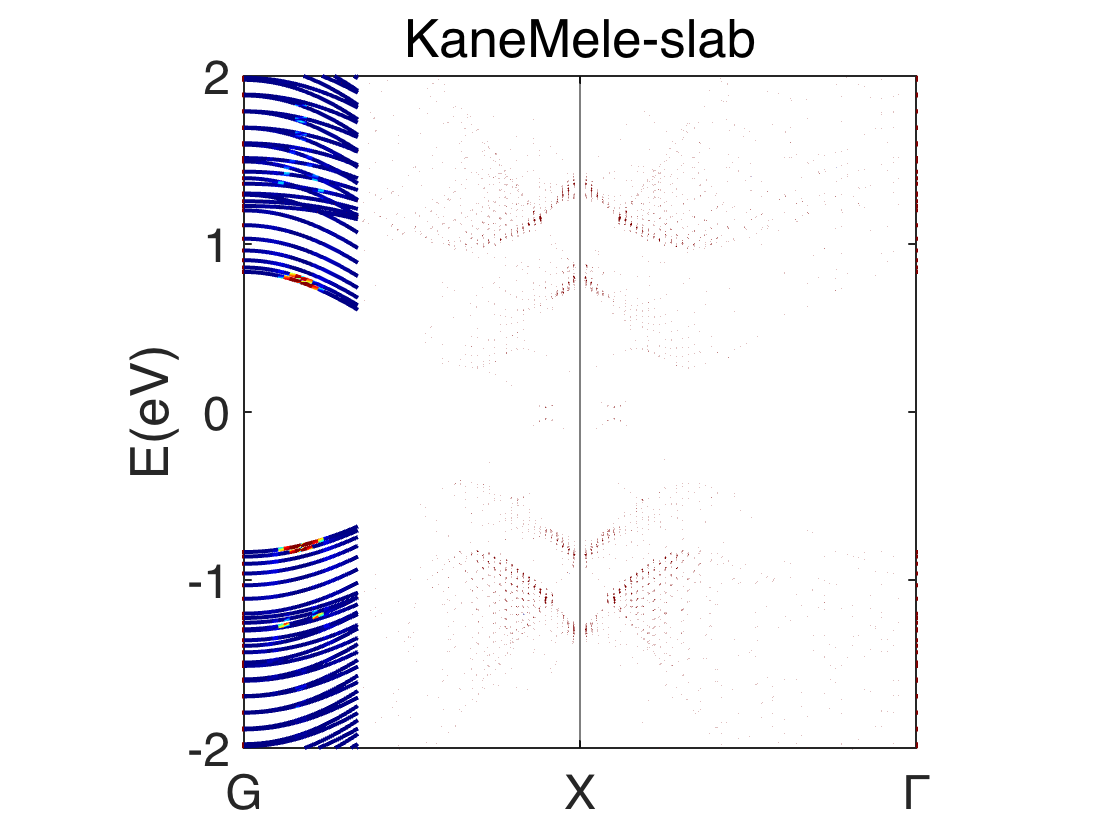

[fig,ax] = vasplib_tool.creat_figure();
vasplib.pbandplot(abs(WEIGHTCAR_slab),EIGENCAR_slab, ...
    'Ecut',[-2,2], ...
    'title','KaneMele-slab', ...
    'KPOINTS','KPOINTS_slab','fig',fig,'ax',ax);

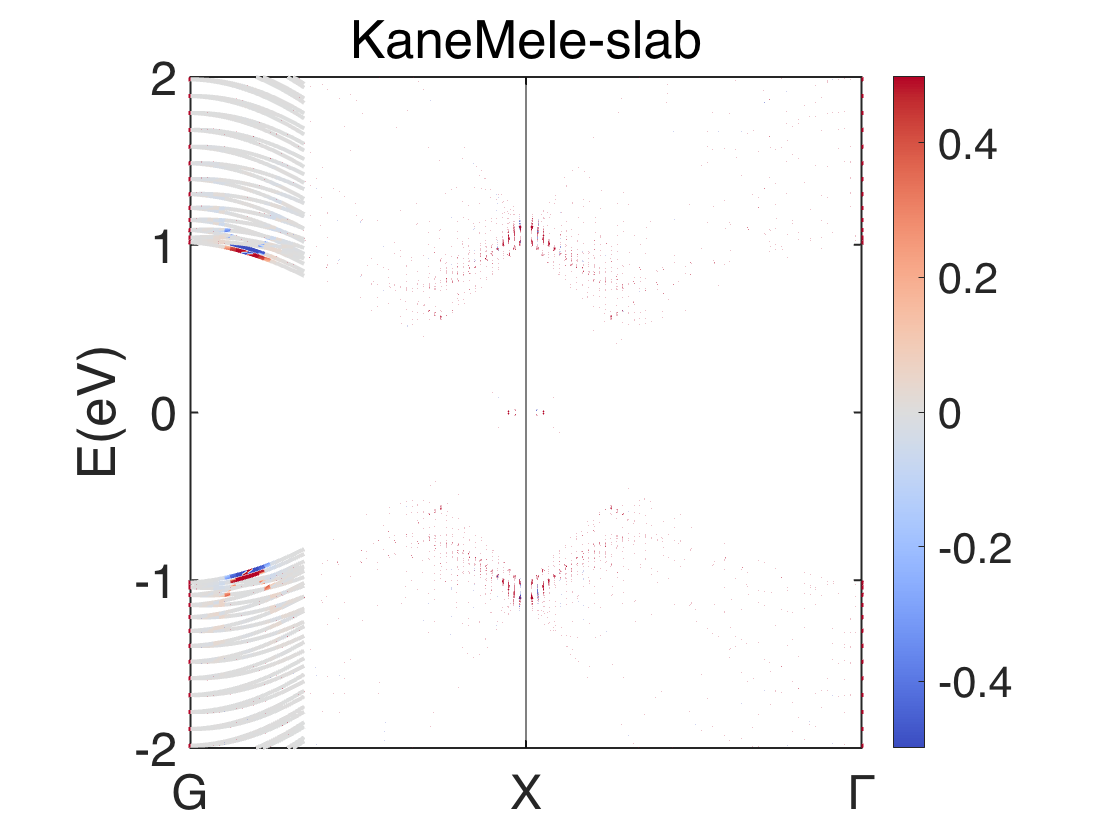

[fig,ax] = vasplib_tool.creat_figure();
vasplib.pbandplot(WEIGHTCAR_slab,EIGENCAR_slab, ...
    'Ecut',[-2,2], ...
    'title','KaneMele-slab', ...
    'KPOINTS','KPOINTS_slab', ...
    'cmap',ColorMap.Matplotlib('coolwarm'), ...
    'fig',fig,'ax',ax);
colorbar(ax);

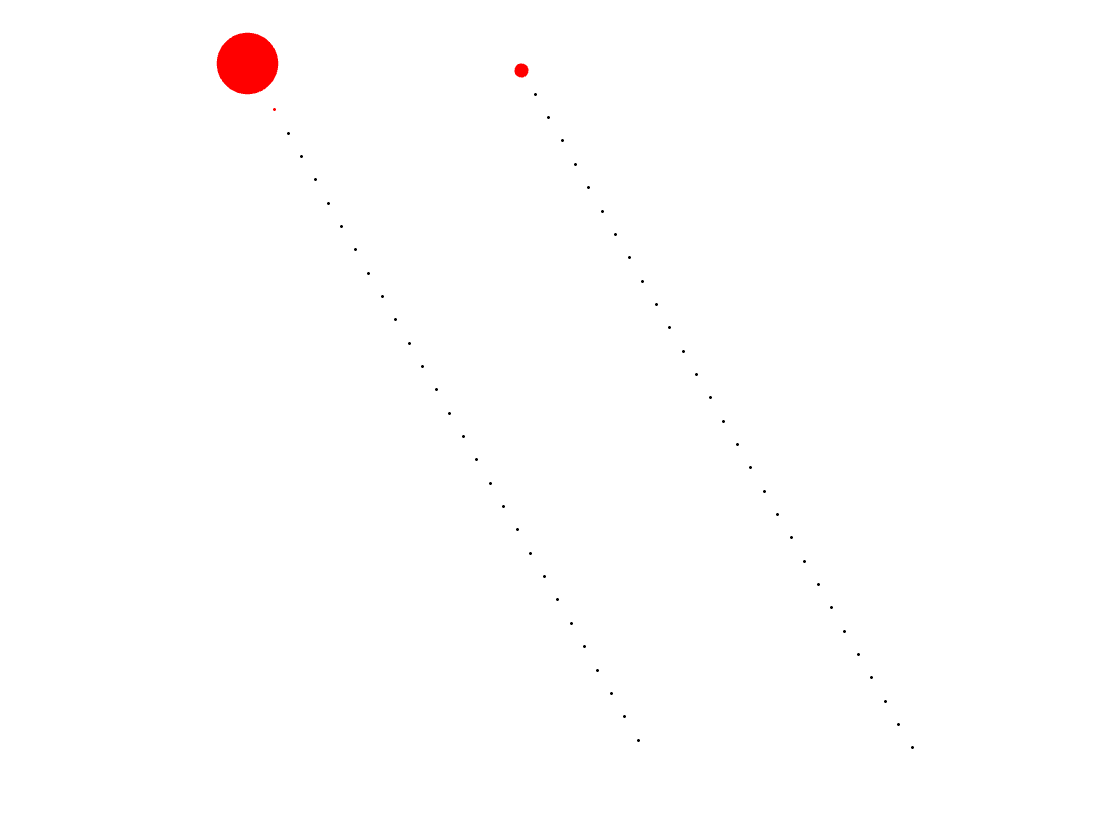

WaveFunc = WAVECAR_slab(:,59:60,60);
orb_list= KaneMele_dy.orbL;
%[fig,ax] = vasplib_tool.creat_figure();
vasplib.waveplot(orb_list,WaveFunc);

### Kane-Mele Armchair

Dont know  how to solve them in only 4 orbital

KaneMele.Rm = sym([sqrt(3),1,0;-1/2,sqrt(3)/2,0;0 0 1/2])

KaneMele =   Htrig - 属性:

          Kinds: 9
          HcoeL: [4×4×9 sym]
          HnumL: [4×4×9 double]
     HsymL_trig: [1    cos(k_x/2)*sin(k_x/2)    sin(k_x/2)*cos((3^(1/2)*k_y)/2)    cos(k_x/2)    cos((3^(1/2)*k_y)/2)    sin((3^(1/2)*k_y)/2)    cos(k_x/2)*cos((3^(1/2)*k_y)/2)    sin(k_x/2)*sin((3^(1/2)*k_y)/2)    cos(k_x/2)*sin((3^(1/2)*k_y)/2)]
      Htrig_sym: [4×4 sym]
      Basis_num: 4
             Rm: [3×3 sym]
             Gk: [3×3 sym]
    symvar_list: [lambda_R    lambda_SO    lambda_v    t]

\left(\begin{array}{cccc} 8\,\lambda _{\mathrm{SO}}\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{k_{x}}{2}\right)-\lambda _{v}-8\,\lambda _{\mathrm{SO}}\,\sin\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right) & -2\,t\,\cos\left(\frac{k_{x}}{2}\right)-t\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)-t\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,1{}\mathrm{i} & 0 & \lambda _{R}\,\cos\left(\frac{k_{

KaneMele.orbL = [     0.333333333         0.666666667         0.50000000 ;...
    0.666666667         0.333333333         0.50000000;...
    0.333333333         0.666666667         0.50000000 ;...
    0.666666667         0.333333333         0.50000000...
    ];
KaneMele.Htrig_sym

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{6}-\lambda_{v}-\sigma_{3} & \sigma_{7} & 0 & \sigma_{5}+\sigma_{4}-\lambda_{R}\,\mathrm{i}+\sigma_{2}+\sigma_{1}\\ \sigma_{8} & \lambda_{v}-\sigma_{6}+\sigma_{3} & \lambda_{R}\,\mathrm{i}-\sigma_{4}+\sigma_{5}-\sigma_{2}+\sigma_{1} & 0\\ 0 & \sigma_{5}+\sigma_{4}-\lambda_{R}\,\mathrm{i}-\sigma_{2}-\sigma_{1} & \sigma_{3}-\sigma_{6}-\lambda_{v} & \sigma_{7}\\ \lambda_{R}\,\mathrm{i}-\sigma_{4}+\sigma_{5}+\sigma_{2}-\sigma_{1} & 0 & \sigma_{8} & \lambda_{v}+\sigma_{6}-\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{3}\,\lambda_{R}\,\sin\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,\mathrm{i}\\ \sigma_{2}=\sqrt{3}\,\lambda_{R}\,\sin\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\\ \sigma_{3}=8\,\lambda_{\mathrm{SO}}\,\sin\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\\ \sigma_{4}=\lambda_{R}\,\cos\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,\mathrm{i}\\ \sigma_{5}=\lambda_{R}\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\\ \sigma_{6}=8\,\lambda_{\mathrm{SO}}\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{k_{x}}{2}\right)\\ \sigma_{7}=-2\,t\,\cos\left(\frac{k_{x}}{2}\right)-t\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)-t\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,\mathrm{i}\\ \sigma_{8}=-2\,t\,\cos\left(\frac{k_{x}}{2}\right)-t\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)+t\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,\mathrm{i} \end{array}$$

B = KaneMele.rotation().Htrig_sym

Setting 21/21Htrig ...


%KaneMele_dy = KaneMele.descritize([0,30,0],'Rotation','auto');
%KaneMele_dy.Htrig_sym

KaneMele = Htrig(4); 
syms a
KaneMele.Rm = sym(a*[1,0,0;-1/2,sqrt(3)/2,0;0 0 2/sqrt(3)])

KaneMele =   Htrig - 属性:

          Kinds: 1
          HcoeL: [4×4 sym]
          HnumL: [4×4 double]
     HsymL_trig: 1
      Htrig_sym: [4×4 sym]
      Basis_num: 4
             Rm: [3×3 sym]
             Gk: [3×3 sym]
    symvar_list: [1×0 sym]

\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)

KaneMele_Rm =KaneMele.Rm

$$KaneMele\_Rm = \left(\begin{array}{ccc} a & 0 & 0\\ -\frac{a}{2} & \frac{\sqrt{3}\,a}{2} & 0\\ 0 & 0 & \frac{2\,\sqrt{3}\,a}{3} \end{array}\right)$$

KaneMele_Gk = KaneMele.Gk

$$KaneMele\_Gk = \left(\begin{array}{ccc} \frac{2\,\pi }{a} & \frac{2\,\pi \,\sqrt{3}}{3\,a} & 0\\ 0 & \frac{4\,\pi \,\sqrt{3}}{3\,a} & 0\\ 0 & 0 & \frac{\pi \,\sqrt{3}}{a} \end{array}\right)$$

inv(KaneMele_Gk/(2*pi)).'

$$ans = \left(\begin{array}{ccc} a & 0 & 0\\ -\frac{a}{2} & \frac{\sqrt{3}\,a}{2} & 0\\ 0 & 0 & \frac{2\,\sqrt{3}\,a}{3} \end{array}\right)$$

syms hat_x hat_y hat_z
syms hat_1 hat_2 hat_3
 KaneMele_Gk*[hat_x;hat_y;hat_z]

$$ans = \left(\begin{array}{c} \frac{2\,\pi \,{\mathrm{hat}}_{x}}{a}+\frac{2\,\pi \,\sqrt{3}\,{\mathrm{hat}}_{y}}{3\,a}\\ \frac{4\,\pi \,\sqrt{3}\,{\mathrm{hat}}_{y}}{3\,a}\\ \frac{\pi \,\sqrt{3}\,{\mathrm{hat}}_{z}}{a} \end{array}\right)$$

## 参考文献

- [GrapheneTB(H(k) sin cos)](https://cpb-us-w2.wpmucdn.com/u.osu.edu/dist/3/67057/files/2018/09/graphene_tight-binding_model-1ny95f1.pdf)

- [KaneMeleTB-zigzag](https://journals.aps.org/prb/pdf/10.1103/PhysRevB.88.245115)

- [KaneMeleTB-Armchair](https://arxiv.org/abs/1408.4507)

- [DescritizeTB technique in square lattice](https://journals.aps.org/prb/pdf/10.1103/PhysRevB.48.11851)

- Harper equation 